clc; close all; clear all; 

load("Data/data_set.mat");

X=data_set{:,22:1742};
figure;
[coeff,score,latent,tsquared,explained,mu] = pca(X);

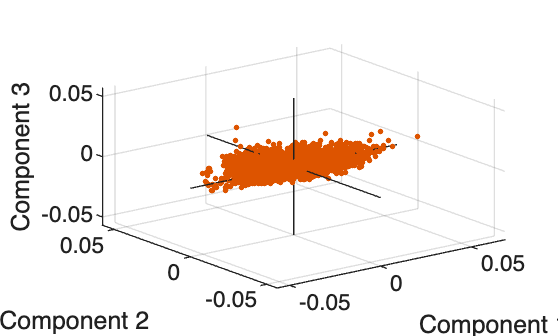


figure;
biplot(coeff(:,1:3), Scores=score(:,1:3));


var_visible= false; %set the visibility for the wavelength's contribution to the PCs
varl = findobj(gca,"Tag","varline");
varl.Visible=false;
varm = findobj(gca,"Tag","varmarker");
varm.Visible=false;

obsm = findobj(gca,"Tag","obsmarker");
%coordinates of points in biplot
bi_X= obsm.XData();
bi_Y= obsm.YData();
bi_Z= obsm.ZData();

figure;
meanSpectra=mean(X)
plot(wavelengths, meanSpectra);
xlabel("Wavelength [nm]");
ylabel("Reflectance");
title("Mean spectrum of the image");


function rgb = vals2colormap(vals, colormap, crange) 
% Take in a vector of N values and return and return a Nx3 matrix of RGB
% values associated with a given colormap
%
% rgb = AFQ_vals2colormap(vals, [colormap = 'jet'], [crange])
%
% Inputs:
% vals     = A vector of values to map to a colormap or a cell array of
%            vectors of values
% colormap = A matlab colormap. Examples: colormap = 'autumn';
%            colormap = 'jet'; colormap = 'hot';
% crange   = The values to map to the minimum and maximum of the colormap.
%            Defualts to the full range of values in vals.
%
% Outputs:
% rgb      = Nx3 matrix of rgb values mapping each value in vals to the
%            corresponding rgb colors.  If vals is a cell array then rgb
%            will be a cell array of the same length
%
% Example:
% vals = rand(1,100);
% rgb = AFQ_vals2colormap(vals, 'hot');
%
% Copyright Jason D. Yeatman, June 2012
% https://github.com/vistalab/vistateach/blob/master/cogneuro/tutorial1_timeseries/vals2colormap.m
if ~iscell(vals)
    if ~exist('crange','var') || isempty(crange)
        crange = [min(vals) max(vals)];
    end
    % Generate the colormap
    cmap = eval([colormap '(256)']);
    % Normalize the values to be between 1 and 256
    vals(vals < crange(1)) = crange(1);
    vals(vals > crange(2)) = crange(2);
    valsN = round(((vals - crange(1)) ./ diff(crange)) .* 255)+1;
    % Convert any nans to ones
    valsN(isnan(valsN)) = 1;
    % Convert the normalized values to the RGB values of the colormap
    rgb = cmap(valsN, :);
elseif iscell(vals)
    if ~exist('crange','var') || isempty(crange)
        crange = [min(vertcat(vals{:})) max(vertcat(vals{:}))];
    end
    % Generate the colormap
    cmap = eval([colormap '(256)']);
    for ii = 1:length(vals)
        % Normalize the values to be between 1 and 256 for cell ii
        valsN = vals{ii};
        valsN(valsN < crange(1)) = crange(1);
        valsN(valsN > crange(2)) = crange(2);
        valsN = round(((valsN - crange(1)) ./ diff(crange)) .* 255)+1;
        % Convert any nans to ones
        valsN(isnan(valsN)) = 1;
        % Convert the normalized values to the RGB values of the colormap
        rgb{ii} = cmap(valsN, :);
    end
end
return
end

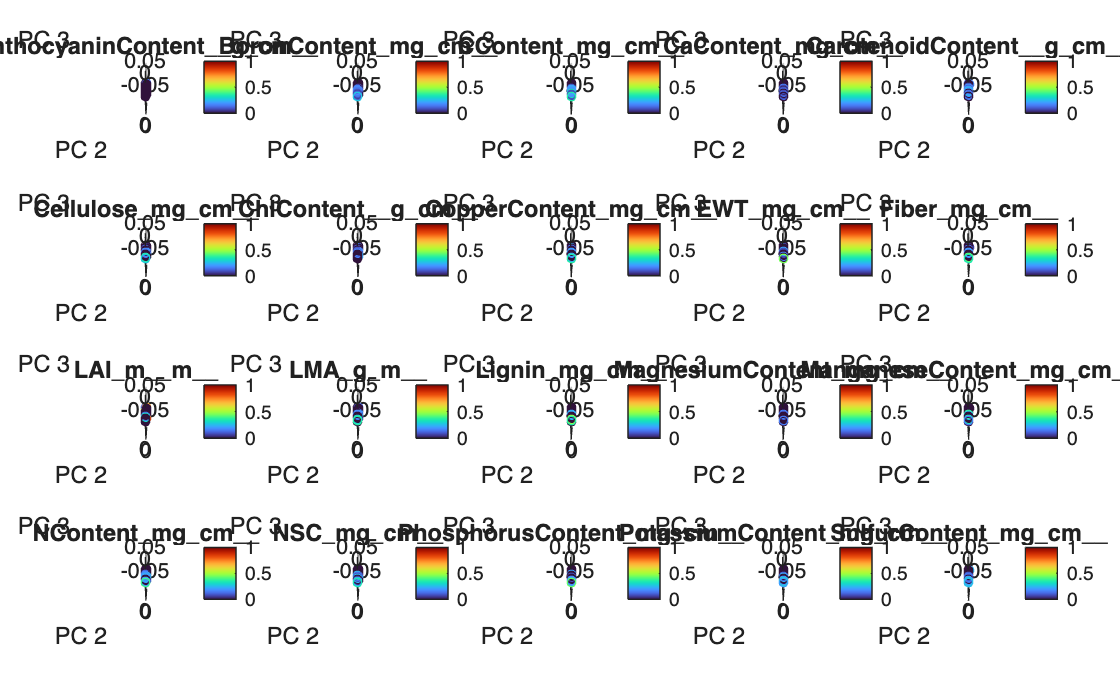

%Manual biplot taking values from biplot, so we can color it

figure;
column_names = data_set.Properties.VariableNames;
for i = linspace(2,21,20)
    nexttile;
    color_Column = data_set{:,i};
    
    rgb=vals2colormap(color_Column,'turbo',[min(color_Column),max(color_Column)]);
    scatter3(bi_X,bi_Y,bi_Z,10,rgb);
    hold on 
    % plot3(coeff(:,1),coeff(:,2),coeff(:,3))
    % un-comment preceding line to show the vectors of the individual
    % wavelengths
    xlabel("PC 1")
    limits =[min(bi_X), max(bi_X)];
    xlim(limits)
    ylim(limits)
    zlim(limits)
    ylabel("PC 2")
    zlabel("PC 3")
    colormap('turbo');
    colorbar
    title(column_names(i))
    hold off
end

%Determine number of PCs needed with 95% of variation explained
idx = find(cumsum(explained)>95,1)

idx = 3